## **AOMIC PIOP1 Replication Sample - Region-Specific Coupling All Conditions - 4 Measures **

Computation of region-specific SC-FC coupling maps (measure that is able to explain the highest variance in FC across all participants most frequently) and creation of correlation matrix depicting the similarity between vectors of regional SC-FC coupling pattern. 

Before running this script: 

- run all scripts in AOMIC Data Prep

**1. Create a group-average map depicting the regional SC-FC coupling pattern for each condition **

1.1. Create a cell that contains for each subject a vector of 4 predictors for each node 

for i = 1:126
    x = final_r_all_AOMIC_PIOP1_gender_126{i,3};% change here to switch between the 6 conditions(rest/task) 
    for j = 1:358
    Node_all_baseline_best_measures_AOMIC_PIOP1_r2{i,j} = x(j,:);
    end
end


1.2. Create a cell containing information about all subjects and coupling measures per node

% extract for each collumn 4 rows from each row and put them together in a matrix (--> I need 126*4 matrix for each node)

n = size(Node_all_baseline_best_measures_AOMIC_PIOP1_r2,2);
All_Nodes_complete_baseline_best_measures_AOMIC_PIOP1_r2 = cell(1,n);
for j = 1:n
    All_Nodes_complete_baseline_best_measures_AOMIC_PIOP1_r2{j} = vertcat(Node_all_baseline_best_measures_AOMIC_PIOP1_r2{:,j});
end 

1.3. Collect the highest coupling value and the respective coupling measure per node 

Max_values_individuals_AOMIC_PIOP1 = zeros(126,358);
Max_indices_individuals_AOMIC_PIOP1 = zeros(126,358);

for i = 1:358
    node_values = All_Nodes_complete_baseline_best_measures_AOMIC_PIOP1_r2{1,i};

    for p = 1:126
        individual_values = node_values(p,:);
        max_r2 = max(individual_values);
        idx_max = find(individual_values == max_r2); 
        
        if size(idx_max,2) == 2
            idx_max = idx_max(randi(length(idx_max),1)) %if two values have the exact same magnitude that this is randomly picking one out of the two 
        end
        
        Max_values_individuals_AOMIC_PIOP1(p,i) = max_r2;
        Max_indices_individuals_AOMIC_PIOP1(p,i) = idx_max;

    end
end

1.4. Find out mode for each node (group-based mask) 

Mode_for_all_nodes = zeros(1,358);

for i = 1:358
    all_selected_measures_per_node = Max_indices_individuals_AOMIC_PIOP1(:,i);
    [mode_node,frequency_mode] = mode(all_selected_measures_per_node);
    Mode_for_all_nodes(1,i) = mode_node;
end

1.5. Extract the values per node from measure that was selected with the highest frequency (mode) and average across all participants 

Mean_values_across_all_nodes = zeros(1,358);
Stdev_values_across_all_nodes = zeros(1,358);

for i = 1:358
    
node_values = All_Nodes_complete_baseline_best_measures_AOMIC_PIOP1_r2{1,i};
measure_highest_occurence = Mode_for_all_nodes(i);
node_values_measure_highest_occurence = node_values(:,measure_highest_occurence);

mean_per_node = mean(node_values_measure_highest_occurence);
stdev_per_node = std(node_values_measure_highest_occurence); 

Mean_values_across_all_nodes(1,i) = mean_per_node;
Stdev_values_across_all_nodes(1,i) = stdev_per_node;

end

**2. Create the brain maps**

2.1. Convert cell to mat

Mean_values_across_all_nodes_mat = Mean_values_across_all_nodes % rename the variable here depending on condition that input data is coming from (important for the correlation matrix later)  

Mean_values_across_all_nodes_mat =     0.1553    0.1023    0.1583    0.1973    0.1989    0.2378    0.2361    0.1590    0.1300    0.0735    0.0501    0.0759    0.1912    0.1056    0.0935    0.1687    0.1453    0.1534    0.1899    0.1987    0.1889    0.1657    0.1025    0.0853    0.0475    0.0693    0.0926    0.0610    0.0732    0.1150    0.0969    0.0521    0.1181    0.1015    0.1444    0.0866    0.0835    0.1050    0.0930    0.1545    0.0959    0.0814    0.1141    0.0930    0.0942    0.1036    0.1050    0.0680    0.0858    0.0966


min(Mean_values_across_all_nodes_mat)

ans = 0.0160

max(Mean_values_across_all_nodes_mat)

ans = 0.2666

2.2. Insert a 0 at node 120 & 300

a = Mean_values_across_all_nodes_mat;
b = 0;
idx_120 = 120;
idx_300 = 300;

a = [a(1:length(a)< idx_120),b,a(1:length(a) >= idx_120)];
a = [a(1:length(a)< idx_300),b,a(1:length(a) >= idx_300)];

Mean_values_across_all_nodes_mat_360 = a

Mean_values_across_all_nodes_mat_360 =     0.1553    0.1023    0.1583    0.1973    0.1989    0.2378    0.2361    0.1590    0.1300    0.0735    0.0501    0.0759    0.1912    0.1056    0.0935    0.1687    0.1453    0.1534    0.1899    0.1987    0.1889    0.1657    0.1025    0.0853    0.0475    0.0693    0.0926    0.0610    0.0732    0.1150    0.0969    0.0521    0.1181    0.1015    0.1444    0.0866    0.0835    0.1050    0.0930    0.1545    0.0959    0.0814    0.1141    0.0930    0.0942    0.1036    0.1050    0.0680    0.0858    0.0966


Mean_values_across_all_nodes_mat_360(120) = NaN;
Mean_values_across_all_nodes_mat_360(300)= NaN;

2.3. Plot

annotName = 'hcp-mmp-b'

annotName = 'hcp-mmp-b'

dataVec = Mean_values_across_all_nodes_mat_360

dataVec =     0.1553    0.1023    0.1583    0.1973    0.1989    0.2378    0.2361    0.1590    0.1300    0.0735    0.0501    0.0759    0.1912    0.1056    0.0935    0.1687    0.1453    0.1534    0.1899    0.1987    0.1889    0.1657    0.1025    0.0853    0.0475    0.0693    0.0926    0.0610    0.0732    0.1150    0.0969    0.0521    0.1181    0.1015    0.1444    0.0866    0.0835    0.1050    0.0930    0.1545    0.0959    0.0814    0.1141    0.0930    0.0942    0.1036    0.1050    0.0680    0.0858    0.0966


ans = struct with fields:
      border: 1
        cMap: [15×3 double]
      newFig: 1
    valRange: [0 0.3500]
    viewcMap: 1
     viewStr: 'all'


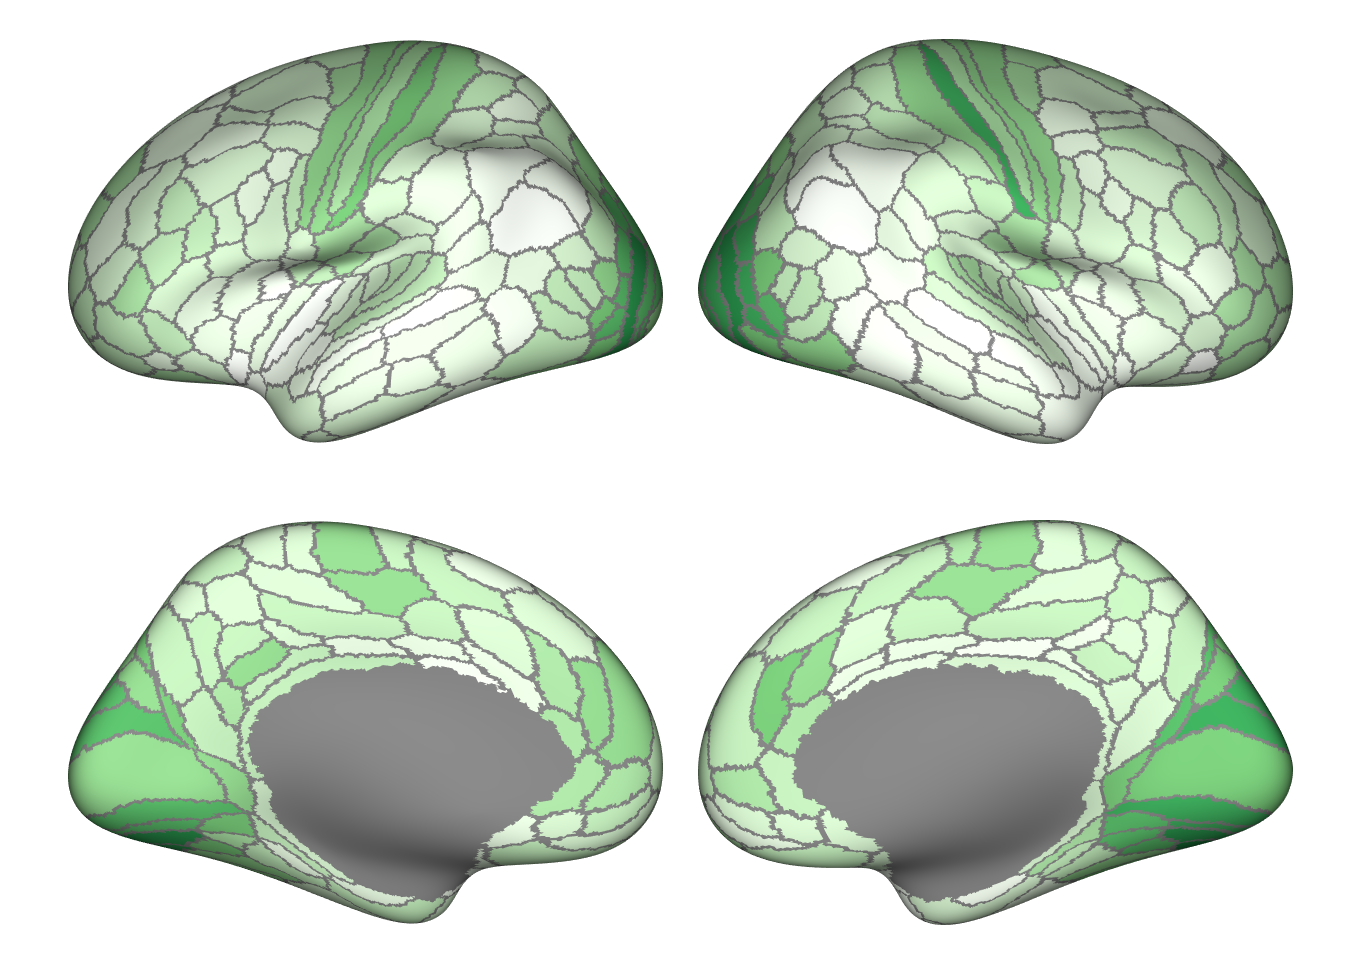

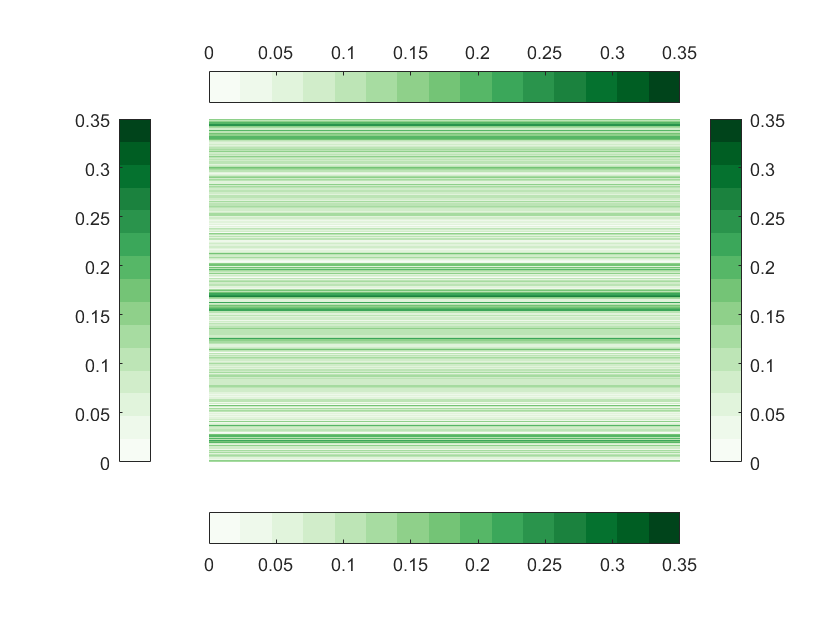

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


parc_plot(surfStruct,annotMap,annotName,dataVec,'cMap',brewermap(15,'Greens'),...
    'viewcMap',1, 'valRange', ([0 0.35]))

**3. Create the brain maps (Stdev)**

3.1. Convert cell to mat

Stdev_values_across_all_nodes_mat = Stdev_values_across_all_nodes % rename the variable here depending on condition that input data is coming from (important for the correlation matrix later)

Stdev_values_across_all_nodes_mat =     0.0760    0.0666    0.0736    0.0798    0.0791    0.0429    0.1005    0.0505    0.0600    0.0728    0.0522    0.0579    0.0838    0.0386    0.0738    0.0789    0.0704    0.0747    0.0938    0.1044    0.0577    0.0903    0.0668    0.0460    0.0289    0.0441    0.0432    0.0402    0.0681    0.0475    0.0494    0.0339    0.0439    0.0417    0.0471    0.0510    0.0663    0.0691    0.0454    0.0538    0.0778    0.0541    0.0792    0.0648    0.0559    0.0578    0.0463    0.0524    0.0574    0.0559


min(Stdev_values_across_all_nodes_mat)

ans = 0.0173

max(Stdev_values_across_all_nodes_mat)

ans = 0.1044

3.2. Insert a 0 at node 120 & 300

a = Stdev_values_across_all_nodes_mat;
b = 0;
idx_120 = 120;
idx_300 = 300;

a = [a(1:length(a)< idx_120),b,a(1:length(a) >= idx_120)];
a = [a(1:length(a)< idx_300),b,a(1:length(a) >= idx_300)];

Stdev_values_across_all_nodes_mat_360 = a

Stdev_values_across_all_nodes_mat_360 =     0.0760    0.0666    0.0736    0.0798    0.0791    0.0429    0.1005    0.0505    0.0600    0.0728    0.0522    0.0579    0.0838    0.0386    0.0738    0.0789    0.0704    0.0747    0.0938    0.1044    0.0577    0.0903    0.0668    0.0460    0.0289    0.0441    0.0432    0.0402    0.0681    0.0475    0.0494    0.0339    0.0439    0.0417    0.0471    0.0510    0.0663    0.0691    0.0454    0.0538    0.0778    0.0541    0.0792    0.0648    0.0559    0.0578    0.0463    0.0524    0.0574    0.0559


Stdev_values_across_all_nodes_mat_360(120) = NaN;
Stdev_values_across_all_nodes_mat_360(300)= NaN;

3.3. Plot

annotName = 'hcp-mmp-b'

annotName = 'hcp-mmp-b'

dataVec = Stdev_values_across_all_nodes_mat_360

dataVec =     0.0760    0.0666    0.0736    0.0798    0.0791    0.0429    0.1005    0.0505    0.0600    0.0728    0.0522    0.0579    0.0838    0.0386    0.0738    0.0789    0.0704    0.0747    0.0938    0.1044    0.0577    0.0903    0.0668    0.0460    0.0289    0.0441    0.0432    0.0402    0.0681    0.0475    0.0494    0.0339    0.0439    0.0417    0.0471    0.0510    0.0663    0.0691    0.0454    0.0538    0.0778    0.0541    0.0792    0.0648    0.0559    0.0578    0.0463    0.0524    0.0574    0.0559


ans = struct with fields:
      border: 1
        cMap: [15×3 double]
      newFig: 1
    valRange: [0 0.1000]
    viewcMap: 1
     viewStr: 'all'


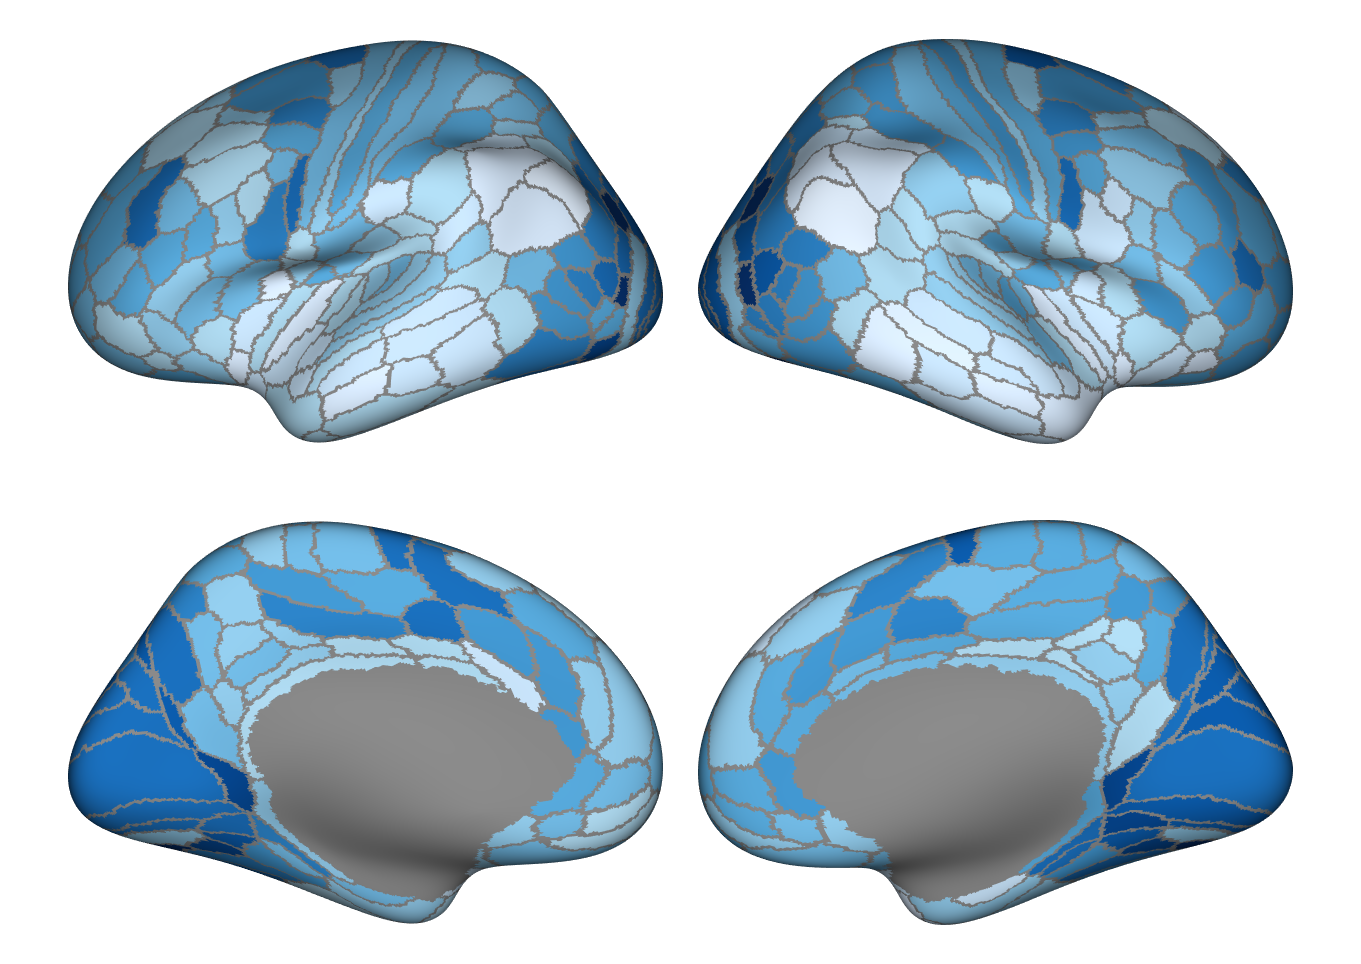

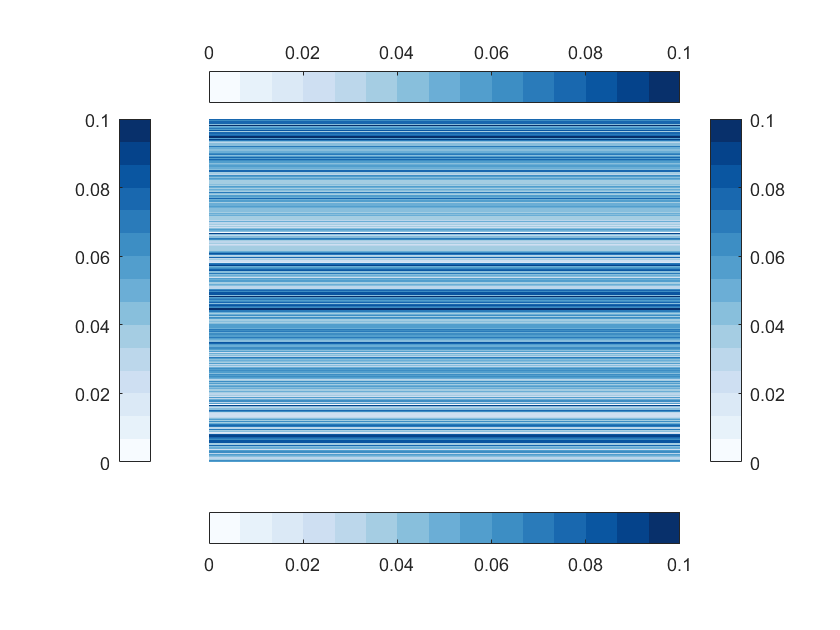

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


parc_plot(surfStruct,annotMap,annotName,dataVec,'cMap',brewermap(15,'Blues'),...
    'viewcMap',1, 'valRange', ([0 0.1]))

**4. Creation of correlation matrix depicting the similarity of condition-specific SC-FC coupling patterns **

4.1. Create the correlation matrix 

coupling_vectors_all_conditions = [Mean_values_across_all_nodes_rest' Mean_values_across_all_nodes_wm' Mean_values_across_all_nodes_emo_anti' Mean_values_across_all_nodes_emo_match' Mean_values_across_all_nodes_face' Mean_values_across_all_nodes_gender']

Unrecognized function or variable 'Mean_values_across_all_nodes_rest'.

correlation_matrix = corrcoef(coupling_vectors_all_conditions)

4.2. Plot the correlation matrix

imagesc(correlation_matrix)
colorbar
set(gca, 'XTick', 1:6); % center x-axis ticks on bins
set(gca, 'YTick', 1:6); % center y-axis ticks on bins
xticklabels({'rest', 'wm', 'emo anti','emo match' ,'face' , 'gender'})
set(gca,'xaxisLocation','top')
yticklabels({'rest', 'wm', 'emo anti','emo match' ,'face' , 'gender'})
title('Correlation between condition-specific coupling measures', 'FontSize', 10); % set title
colormap('jet'); % Choose jet or any other color scheme
colorbar; 
caxis([.73 1]);